# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Práctica 3. Segmentación de Imágenes**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es): Franck Michael Fierro Chicaiza**

**Fecha: 07/11/2023**

El **objetivo** principal de esta práctica es familiarizarse con las técnicas de segmentación de imágenes:

- Desde niveles más sencillos que requieren intervención por parte del usuario (segmentación supervisada) para fijar umbrales, establecer los parámetros de los modelos etc., hasta niveles más complejos que trabajan de forma automática o semi-automática (segmentación no supervisada).

- A partir de técnicas basadas en el histograma, técnicas de agrupamiento (clustering) en regiones y técnicas de bordes. 

- Basadas en métodos lineales y no lineales de clasificación de cada píxel de la imagen en la región que le corresponda.

 A lo largo de la práctica se solicitará que: 

- Se aplique, de forma práctica algunas de las técnicas de segmentación estudiadas, verificando la problemática y limitaciones de las mismas.

- Se compare unas técnicas de segmentación con otras, analizando el porcentaje de acierto de las mismas.

- Se distinga la segmentación supervisada frente a la no supervisada.

- Se diferencie la segmentación basada en técnicas lineales frente a no lineales.

Se recomienda realizar pruebas adicionales (modificando parámetros, utilizando otras imágenes que resalten algún efecto del procesamiento, etc.), analizar los problemas surgidos en la ejecución de la práctica y solución proporcionada, etc. Realice cada ejercicio como sección independiente, visualizando los resultados conjuntamente con subplot cuando sea conveniente, e insertando instrucciones para cerrar ventanas (*close all*), eliminar las variables del *workspace *(*clear all*) y pausar (*pause*), donde considere necesario. 

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 3.

clear;

**Ejercicios propuestos:**

** 1. Segmentación del histograma supervisada lineal:**

- Abra la imagen "pimientos.jpg".

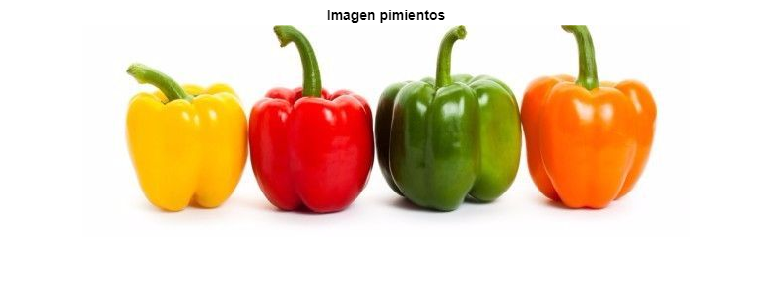

% Cargamos la imagen
I = imread('./imagenes/pimientos.jpg');
figure; imshow(I); title('Imagen pimientos');

imfinfo('./imagenes/pimientos.jpg').ColorType

ans = 'truecolor'

- Conviértala en imagen en niveles de gris.

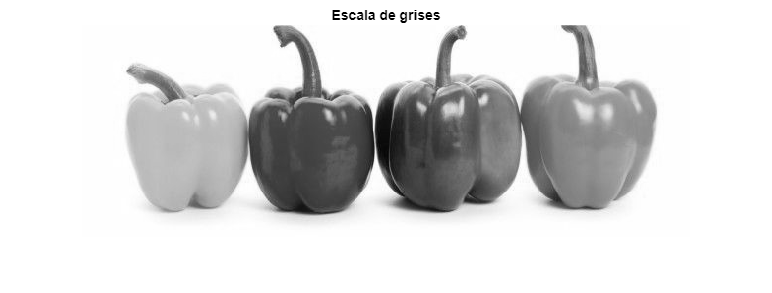

% Obtenemos la imagen en nivel de grises
I_gray = rgb2gray(I);
figure; imshow(I_gray); title('Escala de grises');

- Calcule y muestre el histograma de la imagen en niveles de gris.

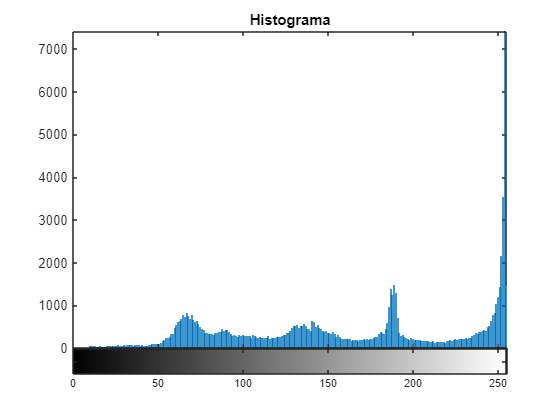

% Mostramos el histograma
figure; imhist(I_gray); title('Histograma')

- A la vista del histograma, utilice tantos umbrales como sea necesario y de los valores adecuados para segmentar cada uno de los objetos de la imagen. Puede introducirlos con un control deslizante (*numeric slider*) o pidiéndolos en el prompt de Matlab con la instrucción: umbral = input('Introduce valor del umbral X a la vista de la figura del histograma '). 

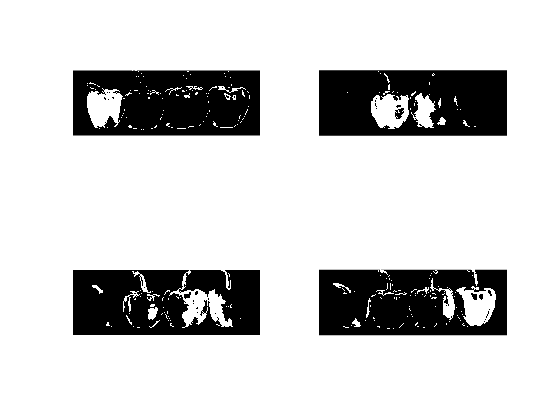


I_seg1 = (I_gray >= 179 & I_gray < 221);
I_seg2 = (I_gray >= 36 & I_gray < 86);
I_seg3 = (I_gray >= 81 & I_gray < 136);
I_seg4 = (I_gray >= 121 & I_gray < 173);

figure; 
subplot(2,2,1), imshow(I_seg1);
subplot(2,2,2), imshow(I_seg2);
subplot(2,2,3), imshow(I_seg3);
subplot(2,2,4), imshow(I_seg4);

- Visualice la segmentación (o con los objetos de distinto color en la misma imagen, o utilizando una imagen diferente para cada objeto).

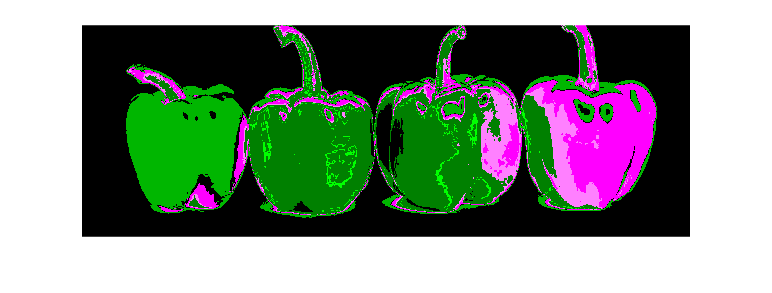

fuse1 = imfuse(I_seg1, I_seg2);
fuse2 = imfuse(fuse1, I_seg3);
fuse3 = imfuse(fuse2, I_seg4);
figure; imshow(fuse3);

- ¿Es fácil segmentar los distintos objetos? Justifique su respuesta.

Comentario:

- Intente mejorar el resultado partiendo de la imagen en color y/o de sus distintas componentes.

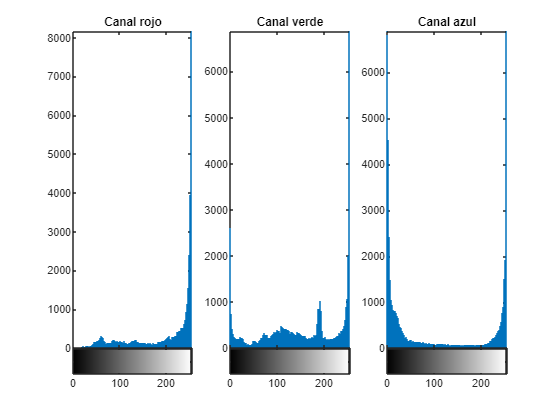


% Separamos los colores de la imagen
r_pimiento = I(:, :, 1);
g_pimiento = I(:, :, 2);
b_pimiento = I(:, :, 3);

figure;
subplot(1,3,1), imhist(r_pimiento); title('Canal rojo');
subplot(1,3,2), imhist(g_pimiento); title('Canal verde');
subplot(1,3,3), imhist(b_pimiento); title('Canal azul');

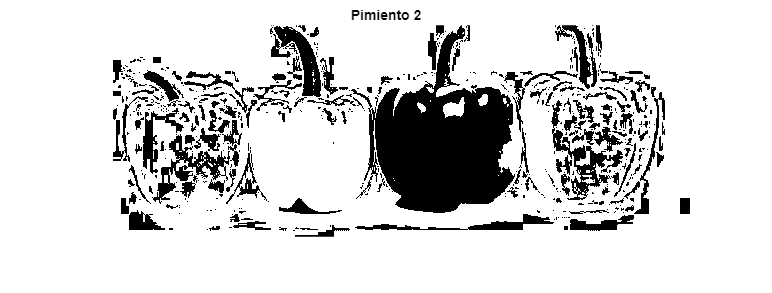


% Formamos el umbral para el pimiento 1

% Formamos el umbral para el pimiento 2
r_pimiento = (r_pimiento >= 143& r_pimiento < 255);
img_final = cat(3, r_pimiento, g_pimiento, b_pimiento);

% Mostramos los resultados
figure, imshow(r_pimiento); title('Pimiento 2');

Comentarios:

**2. Segmentación no supervisada lineal:**

- **Umbralice **la imagen "eight.tif"** con la función *****imbinarize***, utilizando un umbral global calculado previamente con función ***graythresh*** de Matlab (método no supervisado: no requiere la observación del usuario del histograma, ni la elección de umbrales a partir del mismo): 

                    *   La función *graythresh *utiliza el método Otsu para escoger el umbral global de segmentación, minimizando la varianza dentro de los elementos de las clases y maximizándola entre clases.

                    *  La función *imbinarize *umbraliza imágenes en niveles de gris. Si la imagen original está en color es necesario transformarla previamente a niveles de gris, con la función correspondiente dependiendo de su formato (*rgb2gray*, etc...).  

                         level = graythresh(I);

                         BW = *imbinarize*(I,level);

                         figure, imshow(BW)

% Cargamos la imagen
I = imread('./imagenes/eight.tif');
imfinfo('./imagenes/eight.tif').ColorType     % grayscale

ans = 'grayscale'

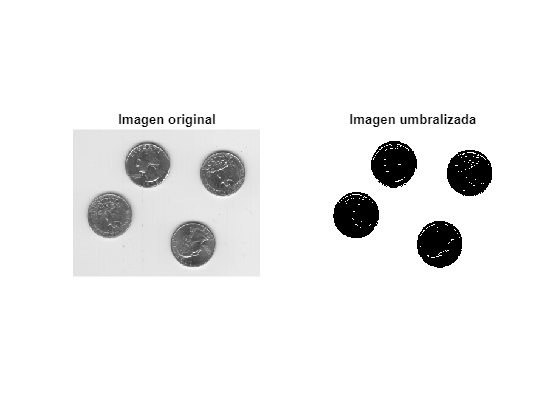

% Buscamos el umbral global
level = graythresh(I);

% Umbralizamos la imagen
BW = imbinarize(I, level);

% Mostramos el resultado
figure, 
subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imshow(BW); title('Imagen umbralizada');

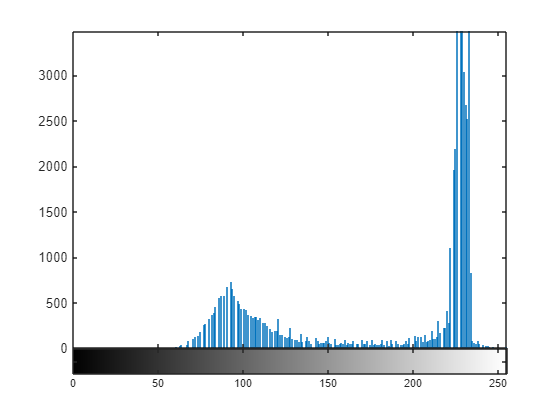

figure, imhist(I);

- ¿Funciona correctamente la segmentación no supervisada con la imagen "eigth.tif"? ¿Porqué?

Comentario:

- Pruebe con otras imágenes de Matlab con histogramas de distintas formas ¿*graythresh* consigue segmentar adecuadamente las imágenes en todos los casos? En caso negativo ¿con qué tipo de imágenes suele funcionar mejor/peor?

% Imagen de granos de arroz
imfinfo('./imagenes/rice.png').ColorType

ans = 'grayscale'

% Imagen de monedas
imfinfo('./imagenes/coins.png').ColorType

ans = 'grayscale'

% Imagen de sangre
imfinfo('./imagenes/blood1.tif').ColorType

ans = 'grayscale'

% Imagen de fruta
imfinfo('./imagenes/pears.png').ColorType

ans = 'truecolor'

% Imagen de pimientos
imfinfo('./imagenes/pimientos.jpg').ColorType

ans = 'truecolor'

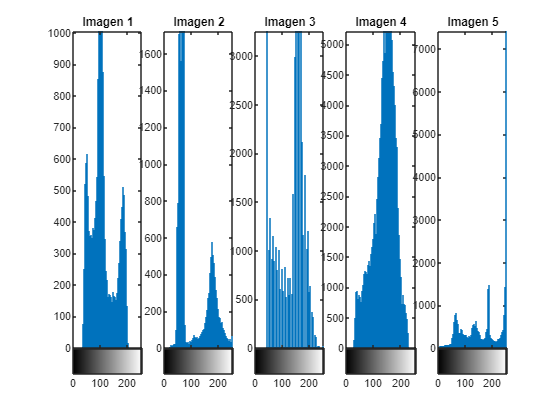

% Imagenes cargadas para realizar pruebas
I_collection = {imread('./imagenes/rice.png'), ...
                imread('./imagenes/coins.png'), ...
                imread('./imagenes/blood1.tif'), ...
                rgb2gray(imread('./imagenes/pears.png')), ...
                rgb2gray(imread('./imagenes/pimientos.jpg'))};

% Mostramos los histogramas
figure,
for i = 1:length(I_collection)
    subplot(1,5,i), imhist(I_collection{i}); title(sprintf('Imagen %d', i));
end

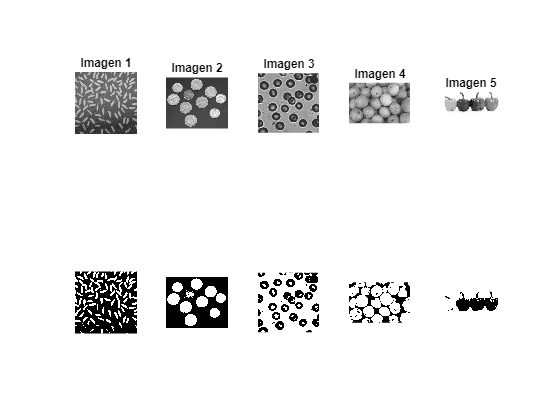

% Mostramos los resultados de la umbralizacion
figure,
for i = 1:length(I_collection)
    level = graythresh(I_collection{i});
    BW = imbinarize(I_collection{i}, level);

    subplot(2,5,i), imshow(I_collection{i}); title(sprintf('Imagen %d', i));
    subplot(2,5,i + 5), imshow(BW);
end

Comentarios:

**3. Compare los dos apartados anteriores: segmentación lineal supervisada frente a no supervisada, indicando ventajas e inconvenientes de cada una.**

**Comentarios:**

**    Ventajas**

**4. Segmentación basada en bordes:**

- Abra la imagen "coins.png".

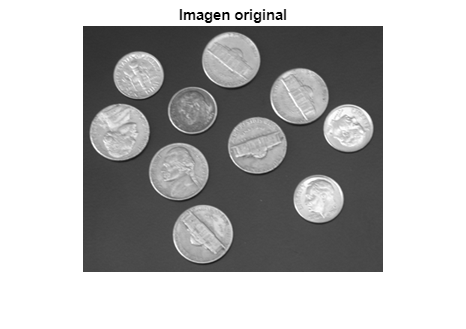

I = imread('./imagenes/coins.png');
figure, imshow(I); title('Imagen original');

- Detecte los bordes utilizando el filtro de Canny. Utilice controles deslizantes (*numeric sliders*) para configurar los distintos parámetros y visualice el efecto de las diferentes configuraciones. Comente los efectos sobre los bordes del cambio de cada parámetro.

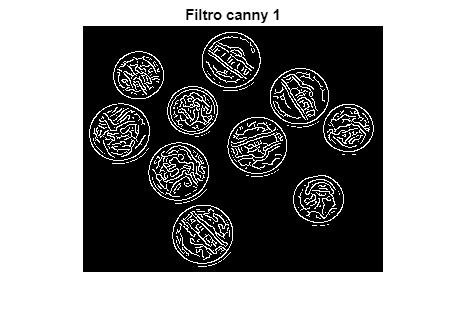

% Configuramos los parametros para el filtro Canny
threshold_low = 0;
threshold_high = 0.06;
sigma = 1;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny 1');

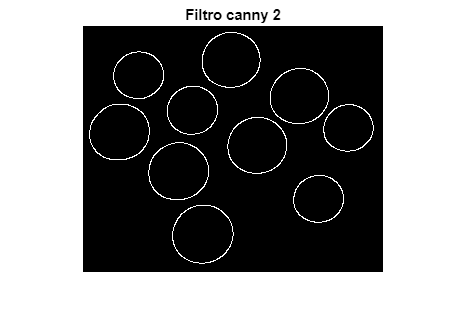

% Configuramos los parametros para el filtro Canny
threshold_low = 0.21;
threshold_high = 0.47;
sigma = 2;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny 2');

- Cierre contornos dilatando los bordes obtenidos (*imdilate*). Visualice.

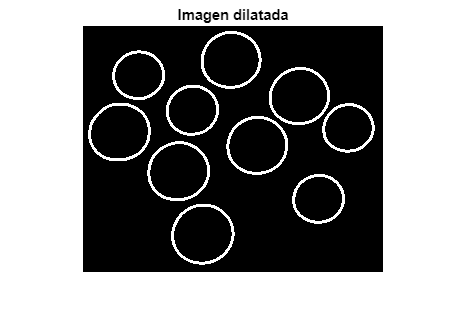

% Seleccionamos el estructurante
se = [0 1 0; 1 1 1; 0 1 0];
% Dilatamos los bordes 
BWdil = imdilate(BW, se);

figure, imshow(BWdil); title('Imagen dilatada');

- Rellene los contornos obtenidos.

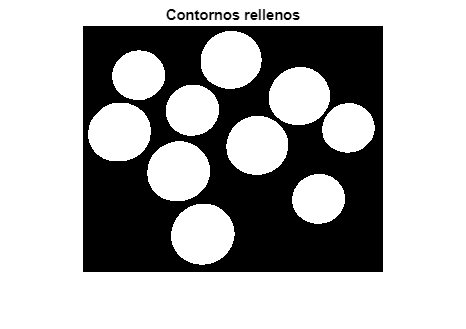

% Rellenamos los contornos
BWfill = imfill(BWdil, 'holes');

% Mostramos el resultado
figure, imshow(BWfill); title('Contornos rellenos');

- Segmente los distintos objetos, etiquetándolos con *bwlabel *y muestre el resultado final.

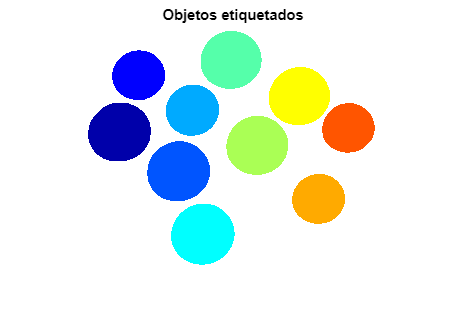

% Etiquetamos los objetos
L = bwlabel(BWfill);
%  Pintamos los objetos
L_RGB_CANNY = label2rgb(L);

% Mostramos el resultado
figure, imshow(L_RGB_CANNY); title('Objetos etiquetados');

- Repita los pasos 1 a 5 utilizando la máscara de `'sobel'``y` compare los resultados (canny - sobel). Justifique.

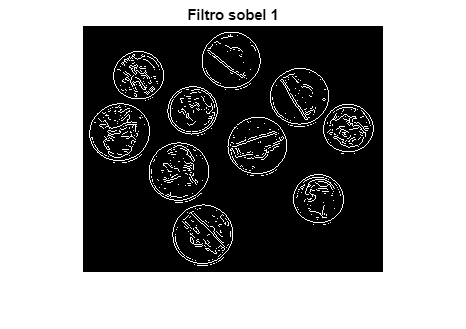

% Tomamos la imagen cargada anteriormente I
% Aplicamos el filtro sobel
BWs = edge(I, 'sobel', (graythresh(I) * .1));

% Mostamos el resultado
figure, imshow(BWs); title('Filtro sobel 1');

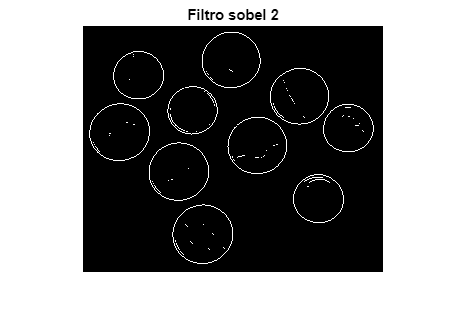

% Aplicamos el filtro sobel
BWs = edge(I, 'sobel', (graythresh(I) * .28));

% Mostamos el resultado
figure, imshow(BWs); title('Filtro sobel 2');

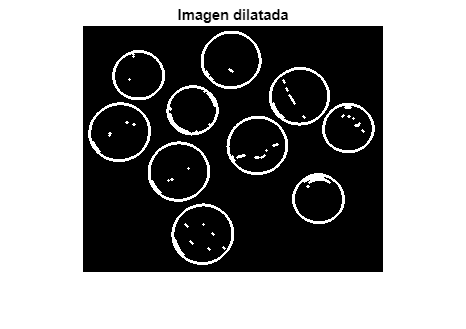

% Seleccionamos el estructurante
se = [0 1 0; 1 1 1; 0 1 0];
% Dilatamos los bordes
BWsdil = imdilate(BWs, se);

figure, imshow(BWsdil); title('Imagen dilatada');

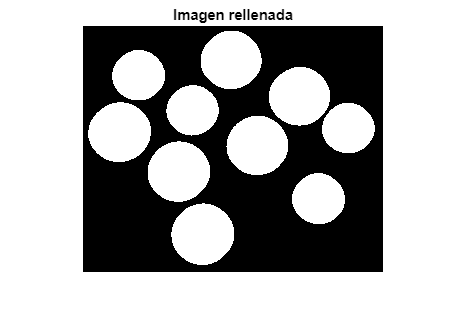

% Rellenamos los bordes
BWrellenada = bwfill(BWsdil,'holes');

figure, imshow(BWrellenada); title('Imagen rellenada');

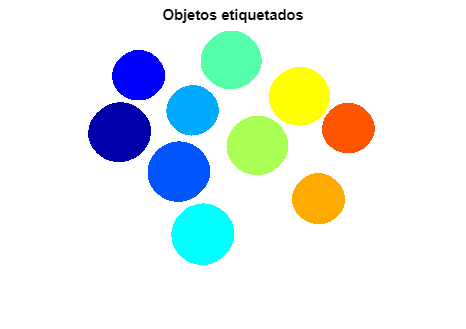

% Etiquetamos los objetos
L = bwlabel(BWrellenada);
% Pintamos los objetos
%numero_objetos = max(max(L));
L_RGB_SOBEL = label2rgb(L); 

figure, imshow(L_RGB_SOBEL); title('Objetos etiquetados');

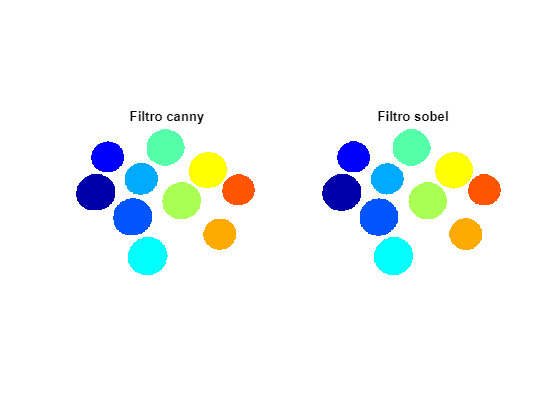

% Comparacion
figure, 
subplot(1,2,1), imshow(L_RGB_CANNY); title('Filtro canny');
subplot(1,2,2), imshow(L_RGB_SOBEL); title('Filtro sobel');

Comentarios:

- Repita los pasos 1 a 5 y compare los resultados realizando o no la dilatación (paso 3). Justifique.

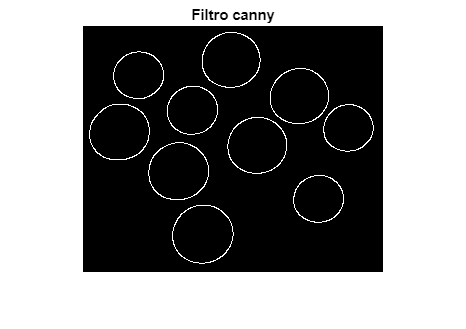

% Tomamos la imagen anteriormente cargada I
% Configuramos los parametros para el filtro Canny
threshold_low = 0.21;
threshold_high = 0.47;
sigma = 2;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny');

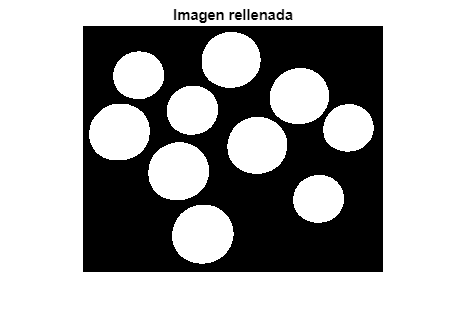

% NO DILATAMOS LA IMAGEN
% Rellenamos los bordes
BWrellenada = bwfill(BW,'holes');

figure, imshow(BWrellenada); title('Imagen rellenada');

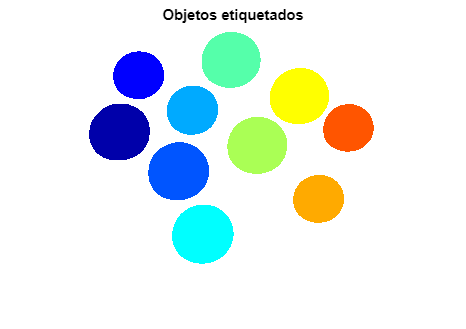

% Etiquetamos los objetos
L = bwlabel(BWrellenada);
% Pintamos los objetos
L_RGB_ND = label2rgb(L); 

figure, imshow(L_RGB_ND); title('Objetos etiquetados');

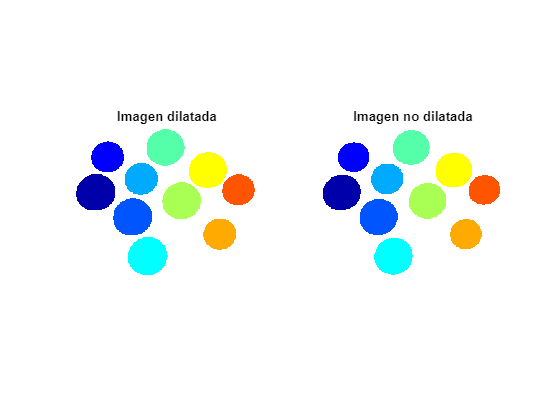

% Comparacion
figure, 
subplot(1,2,1), imshow(L_RGB_CANNY); title('Imagen dilatada');
subplot(1,2,2), imshow(L_RGB_ND); title('Imagen no dilatada');

Comentarios:

- Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación. Justifique.

% Configuramos los parametros para el filtro Canny
threshold_low = 0.21;
threshold_high = 0.47;
sigma = 2;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny 2');


% Seleccionamos el estructurante
se = strel('disk', 1);
% Dilatamos los bordes 
BWdil = imdilate(BW, se);

figure, imshow(BWdil); title('Imagen dilatada');


% Rellenamos los contornos
BWfill = imfill(BWdil, 'holes');

% Mostramos el resultado
figure, imshow(BWfill); title('Contornos rellenos');


% Etiquetamos los objetos
L = bwlabel(BWfill);
%  Pintamos los objetos
L_RGB_CANNY = label2rgb(L);

% Mostramos el resultado
figure, imshow(L_RGB_CANNY); title('Objetos etiquetados');

- Compare los resultados realizando una dilatación (*imdilate*) o un cierre (*imclose*). Justifique.

% Configuramos los parametros para el filtro Canny
threshold_low = 0.21;
threshold_high = 0.47;
sigma = 2;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny 2');

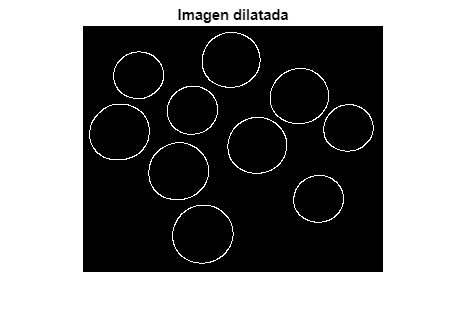


% Seleccionamos el estructurante
se = [0 1 0; 1 1 1; 0 1 0];
% Dilatamos los bordes 
BWdil = imclose(BW, se);

figure, imshow(BWdil); title('Imagen dilatada');

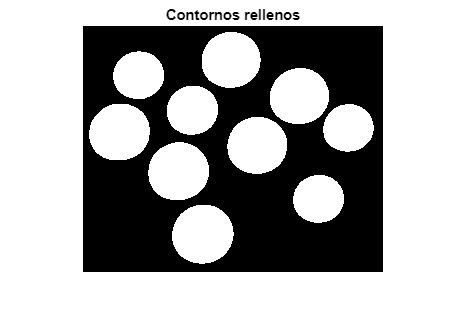


% Rellenamos los contornos
BWfill = imfill(BWdil, 'holes');

% Mostramos el resultado
figure, imshow(BWfill); title('Contornos rellenos');


% Etiquetamos los objetos
L = bwlabel(BWfill);
%  Pintamos los objetos
L_RGB_CANNY = label2rgb(L);

% Mostramos el resultado
figure, imshow(L_RGB_CANNY); title('Objetos etiquetados');

**5. Detección de rectas utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, pinte las 7 rectas más largas de la imagen **'despacho1.jpg'**. 

imfinfo('./imagenes/despacho1.jpg').ColorType

ans = 'truecolor'

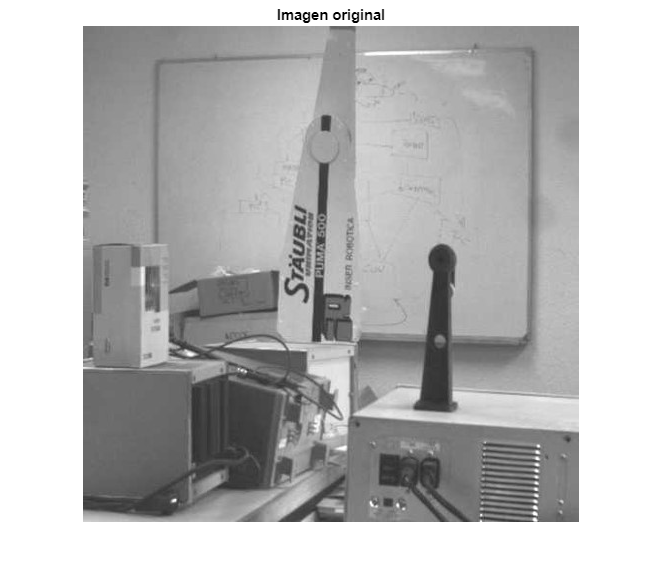

I = rgb2gray(imread('./imagenes/despacho1.jpg'));
figure, imshow(I); title('Imagen original');

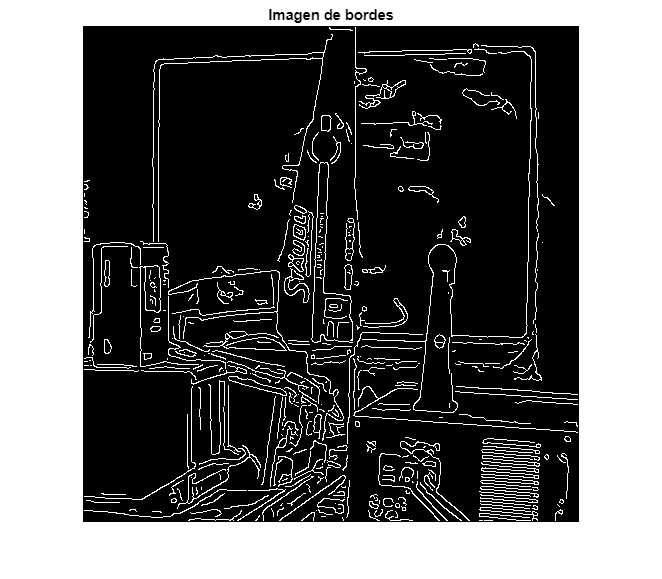

% Aplicamos un filtro canny sobre la imagen
BW = edge(I,'canny');
figure, imshow(BW); title('Imagen de bordes');

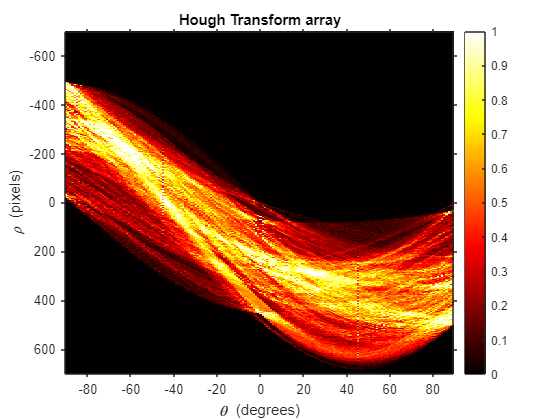

% Calculamos la transforamda de Hough
[H, theta, rho] = hough(BW);

figure,
imshow(imadjust(rescale(H)),'XData',theta,'YData',rho,'InitialMagnification','fit');
title('Hough Transform array'); xlabel('\theta (degrees)'); ylabel('\rho (pixels)'); 
axis on, axis normal; colormap(gca,hot); colorbar;

% Buscamos los picos en la transformada
th = ceil(0.85*max(H(:))); % umbral de búsqueda
max_peaks = 7; % 7 picos

% Coordenadas de los picos
P = houghpeaks(H, max_peaks)

P =          332           5
         742         179
        1150          92
         364           5
         772          91
         974          91
         942          93


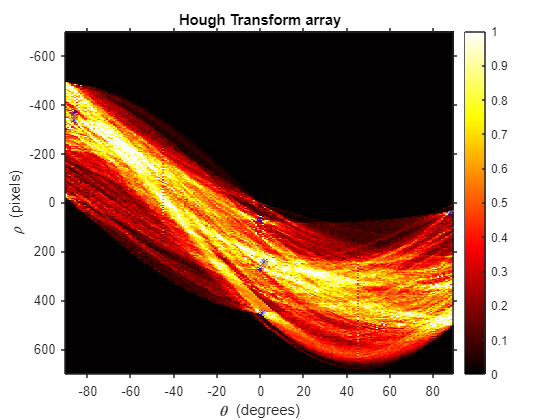

% Mostramos los picos en la imagen
x = theta(P(:,2)); 
y = rho(P(:,1)); 
hold on;
plot(x,y,'*','color','blue');
hold off;

% Obtenemos las 7 lineas largas
lines = houghlines(BW, theta, rho, P, 'FillGap', 90, 'MinLength', 30)

lines = 1×7 struct array with fields:
    point1
    point2
    theta
    rho


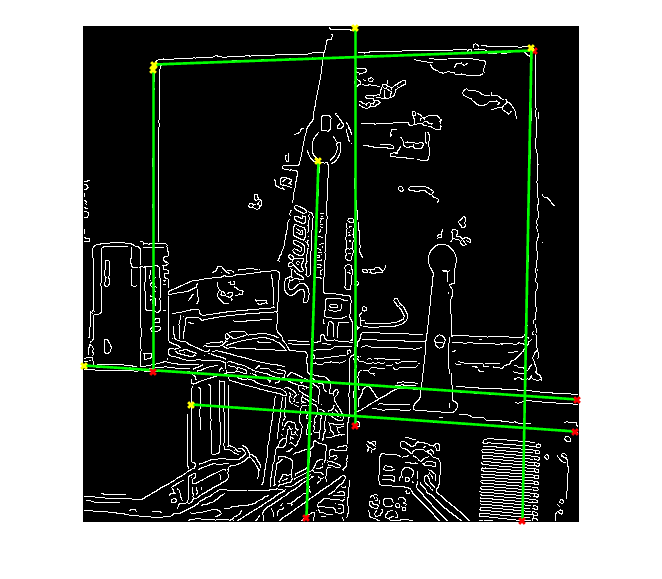

figure, 
imshow(BW), 
hold on 

for k = 1:length(lines)    
    xy = [lines(k).point1; lines(k).point2];    
    
    % dibuja las rectas
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    
    % marca con una cruz el inicio y final de las rectas
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
end 

- Verifique la función de los parámetros 'FillGap' y 'MinLength' modificando su valor (por ejemplo, mediante *sliders*) y visualizando el resultado. Comente su efecto sobre las líneas detectadas.

lines = houghlines(BW, theta, rho, P, 'FillGap', 10, 'MinLength', 4)

lines = 1×45 struct array with fields:
    point1
    point2
    theta
    rho


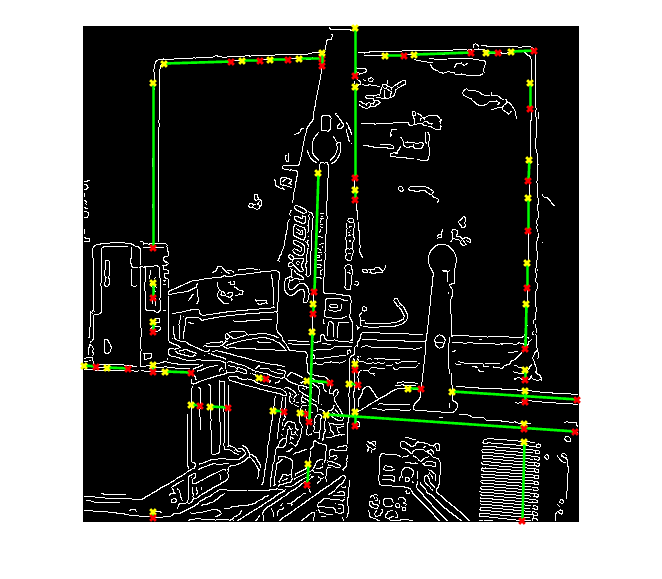

figure, 
imshow(BW), 
hold on 

for k = 1:length(lines)    
    xy = [lines(k).point1; lines(k).point2];    
    
    % dibuja las rectas
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    
    % marca con una cruz el inicio y final de las rectas
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
end 

Comentarios:

- Calcule el número de picos `length(P)` y el número de líneas `length(lines)` obtenidas. ¿Son iguales o diferentes? ¿por qué?

% Numero de picos
length(P)

ans = 7

% Numero de lines
length(lines)

ans = 45

Comentarios:

**6. Detección de círculos utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, localice y pinte el contorno de las células de la imagen **'blood1.tif'** cuyo radio esté entre 7 y 20 píxeles. Si fuera necesario, considere la posibilidad de umbralizar la imagen y/o de invertirla antes de aplicar la transformada.

- Resalte la célula más grande pintándola de un color diferente.

- ¿Cuántas células ha encontrado?

**7. Transformada Watershed:**

- Cargue la imagen `'circles.png'` umbralízela y realize una segmentación utilizando la transformada de Watershed. ¿Existe sobre-segmentación, es decir, se han segmentado muchos más objetos de los que hay en la imagen? En caso de que exista, intente reducirla (utilizando, por ejemplo, operadores morfológicos).

**Opcional.** Umbralización no lineal, para número de clases mayor que 2. En ambos casos se considerará que a la entrada se pueden utilizar imágenes de cualquier tamaño y tipo (indexadas, color y en niveles de gris) que serán siempre convertidas a niveles de gris en primer lugar.

**8. **Implemente un programa que realice la segmentación supervisada por modelos gaussianos (no lineal) para un número de clases superior a 2. 

**9. **Implemente un programa que realice la segmentación no supervisada por modelos gaussianos (no lineal) para un número de clases superior a 2. 